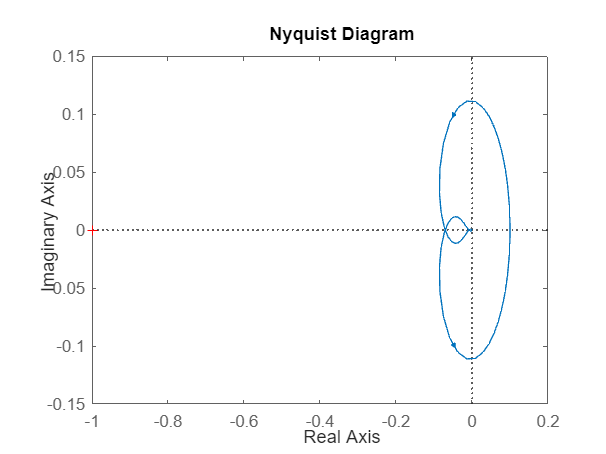

clear;
licz = [1 1];
mian = [0.01 0.5 3 -10 10];
Go_s = tf(licz, mian);
plotoptions = nyquistoptions('cstprefs');
%plotoptions.ShowFullContour = 'off';
figure;
nyquist(Go_s, plotoptions);

is_stable = isstable(feedback(Go_s, 1))

ans = logical
   0


[k_kryt1,~] = margin(Go_s)

k_kryt1 = 14.1376

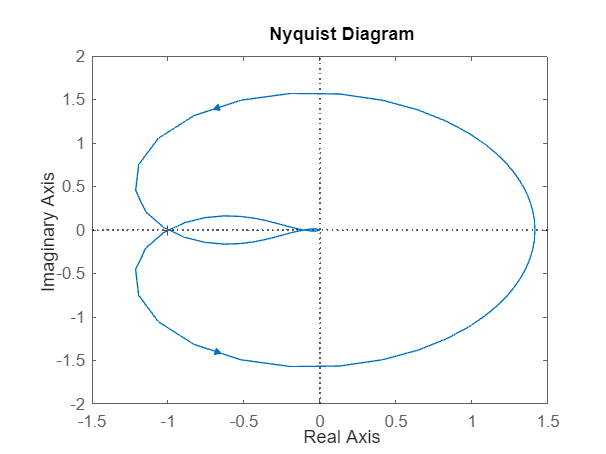


licz1 = k_kryt1 .* licz;
Go_s = tf(licz1, mian);

figure;
nyquist(Go_s, plotoptions);


is_stable = isstable(feedback(Go_s, 1))

ans = logical
   1



step = 0.01;
for k = k_kryt1 + step : step : 150
    licz2 = k .* licz;
    Go_s = tf(licz2, mian);
    if isstable(feedback(Go_s, 1)) == 0
        k_kryt2 = k - step
        break
    end
end

k_kryt2 = 130.8576

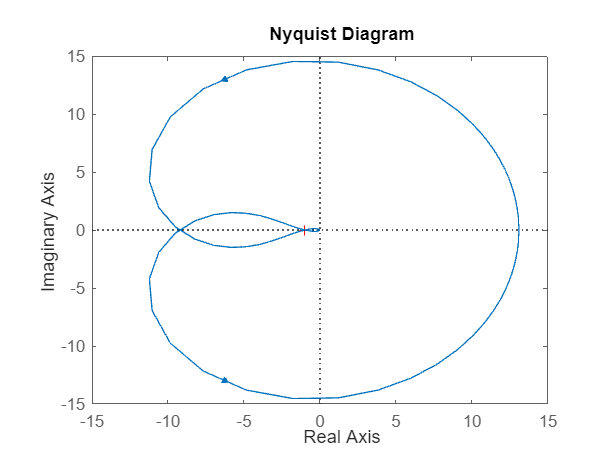


licz3 = k_kryt2 .* licz;
Go_s = tf(licz3, mian);
figure;
nyquist(Go_s, plotoptions);

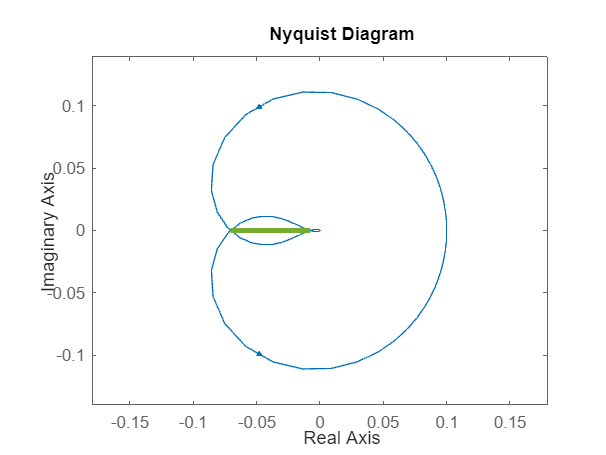

clear;
licz = [1 1];
mian = [0.01 0.5 3 -10 10];
Go = tf(licz, mian);

% Wyrysowanie charakterystyki nyquista dla wzmocnienia 1
plotoptions = nyquistoptions('cstprefs');
%plotoptions.ShowFullContour = 'off';
figure; hold on; nyquist(Go, plotoptions);
axis([-0.18 0.18 -0.14 0.14]);
plot(linspace(-0.0707, -0.0076, 50) ,zeros(1, 50), "LineWidth", 3);
hold off;

Gz = feedback(Go, 1);
% Układ otwarty ma dwa bieguny niestabilne, wobec tego według twierdzenia Nyquista,
% będzie stabilny dla takich wartości k, że zmiana fazy będzie równa 2*2pi
% (2 pełne obroty wektora zaczepionego w punkcie (-1/k, j0),
% którego koniec wodzi po wykresie G(jw), dla w od -nieskończoności do +nieskończoności)
% Bieguny układu otwartego
Go_poles = pole(Go)

Go_poles =  -42.3443 + 0.0000i
 -10.2412 + 0.0000i
   1.2928 + 0.7966i
   1.2928 - 0.7966i


is_stable = isstable(Gz)

is_stable = logical
   0



% Jak widać na wykresie taki przedział istnieje i znajduje się on między
% dwoma miejsami przecięcia z osią rzeczywistą po lewej stronie osi
% urojonej
syms s w real
% Transmitancja operatorowa jako funkcja symboliczna
Go_s(s) = (s + 1) / (0.01 * s^4 + 0.5 * s^3 + 3 * s^2 - 10 * s + 10);
% Transmitancja widmowa
Gw = Go_s(1j*w);
% Częsc rzeczywista transmitancji widmowej
P(w) = real(Gw);
% Czesc urojona transmitancji widmowej
Q = imag(Gw);

$$Q = \begin{array}{l} \frac{\frac{w^{3}}{2}+10\,w}{\sigma_{1}}+\frac{w\,\left(\frac{w^{4}}{100}-3\,w^{2}+10\right)}{\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{w^{4}}{100}-3\,w^{2}+10\right)}^{2}+{\left(\frac{w^{3}}{2}+10\,w\right)}^{2} \end{array}$$

% Wartosci pulsacji, w jakich Q jest rowne zero
w0 = solve(Q == 0);
% Wartosci P, dla ktorych Q == 0
zero_points = double(P(w0));
% Pozstawienie tylko unikalnych pierwiastków po lewej stronie osi urojonej
zero_points = unique(zero_points(zero_points < 0));
% Wzmocnienia krytyczne
k_kryt1 = - 1 / zero_points(1)

k_kryt1 = 14.1369

k_kryt2 = - 1 / zero_points(2)

k_kryt2 = 130.8631

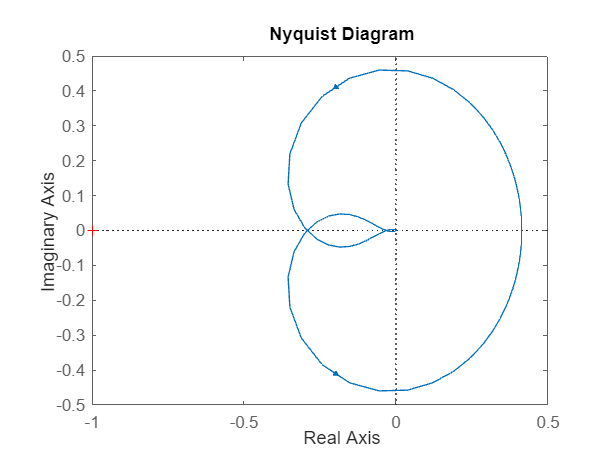


% Charakterystyka nyquista dla wzmocnienia w przedziale stabilności,
% blisko k_kryt1
licz2 = (k_kryt1 - 10.0001) .* licz;
Go = tf(licz2, mian);

figure; nyquist(Go, plotoptions);

is_stable = isstable(feedback(Go, 1))

is_stable = logical
   0


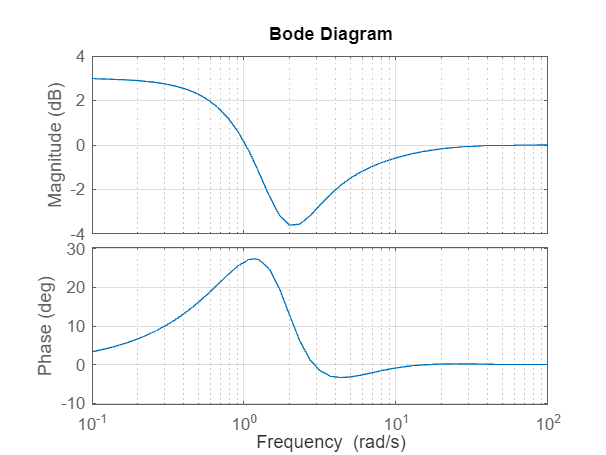

figure; bode(1 + Go); grid on;

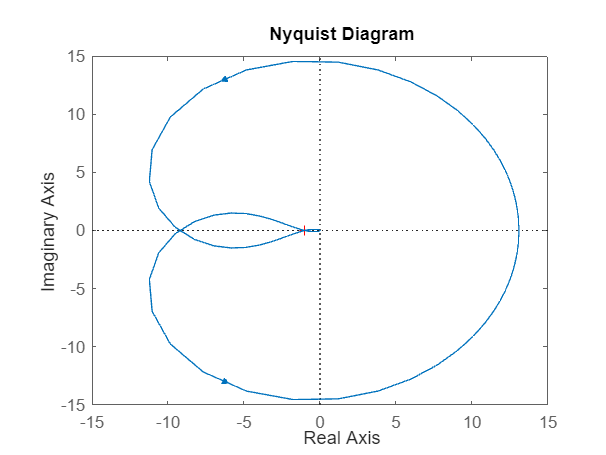

% Charakterystyka nyquista dla wzmocnienia w przedziale stabilności,
% blisko k_kryt2
licz3 = (k_kryt2 - 0.0001) .* licz;
Go = tf(licz3, mian);

figure; nyquist(Go, plotoptions);

is_stable = isstable(feedback(Go, 1))

is_stable = logical
   1


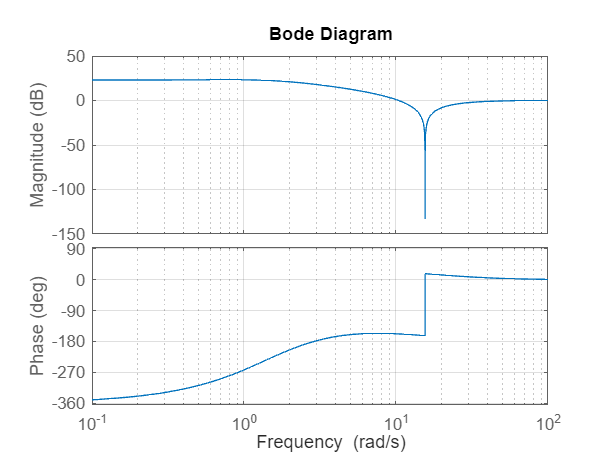

figure; bode(1 + Go); grid on;

Opóźnienie

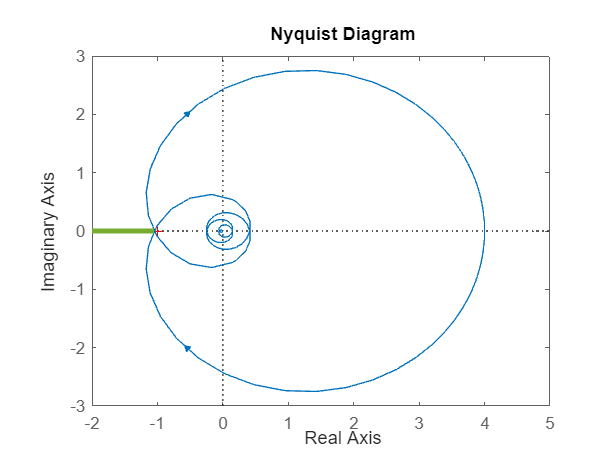

clear;
[del_licz, del_mian] = pade(0.5, 5);
licz = [0 4];
mian = [1 1];
[licz, mian] = series(licz, mian, del_licz, del_mian);
Go = tf(licz, mian);
figure; hold on; nyquist(Go);
axis([-2 5 -3 3]);
plot(linspace(-2, -1.0507, 50) ,zeros(1, 50), "LineWidth", 3);
hold off;


Gz = feedback(Go, 1);
is_Go_stable = isstable(Go)  % otwarty stabilny

is_Go_stable = logical
   1


is_Gz_stable = isstable(Gz)

is_Gz_stable = logical
   0


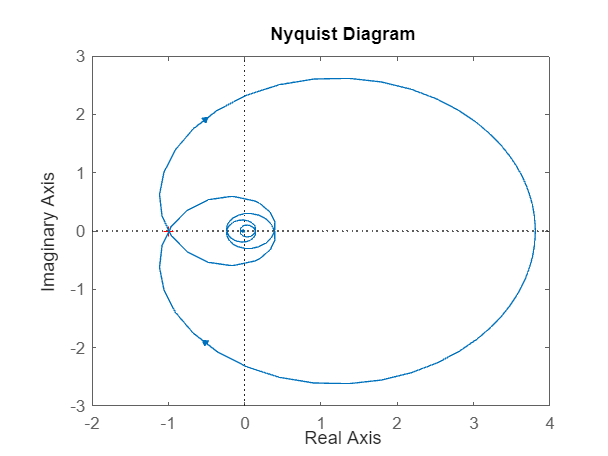


syms s w real
Go_s(s) = (4 * exp(-0.5 * s)) / (s + 1);
Gw = Go_s(1j*w);
P(w) = real(Gw);
Q = imag(Gw);
% Matlab nie daje rady znalezc rozwiazania symbolicznie
% Rozwiazanie numeryczne
w0 = vpasolve(Q == 0, w, -4);
zero_point = double(P(w0));

k_kryt = - 1 / zero_point;
licz2 = (k_kryt) .* licz;
Go = tf(licz2, mian);
figure; nyquist(Go);

is_stable = isstable(feedback(Go, 1))

is_stable = logical
   1


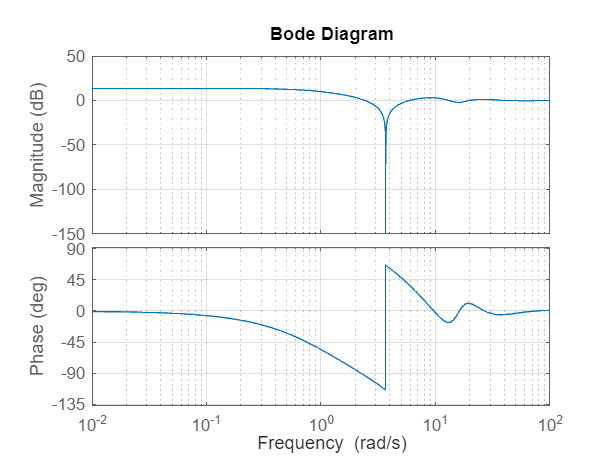

bode(1 + Go); grid on;